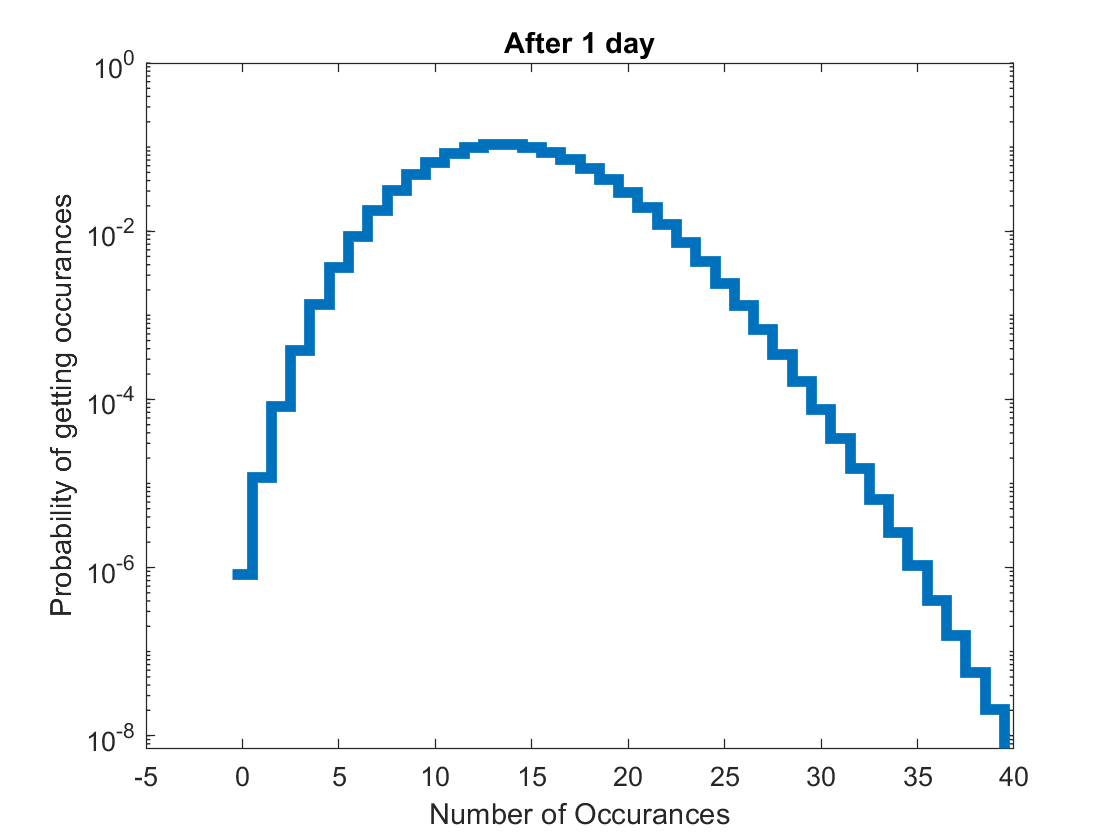

clear, close all, clc

X = 14;
Y = 20;
x = 0:40;
poisson = makedist("Poisson", 'lambda',X);
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')
title("After 1 day")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

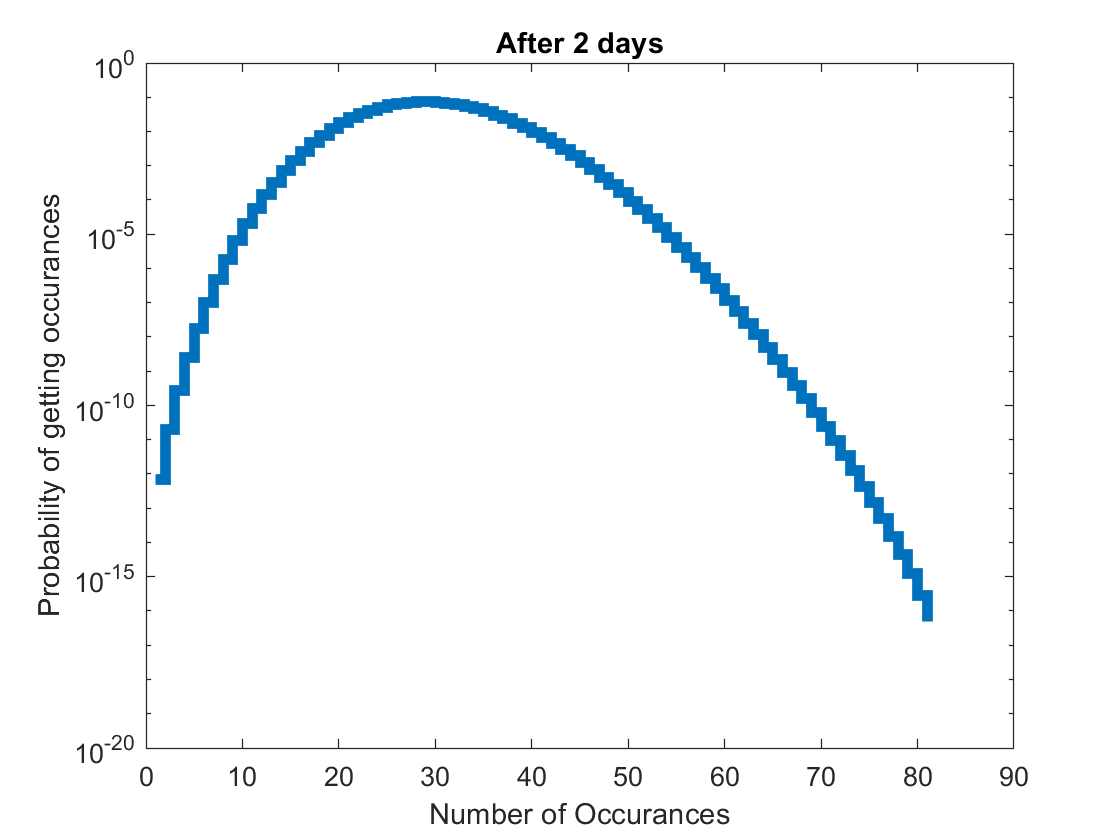

days_1 = pdf(poisson,x);

days_2 = conv(pdf(poisson,x),pdf(poisson,x));
ave_2 = conv(pdf(poisson,x/2),pdf(poisson,x/2));
ave_3 = conv(conv(pdf(poisson,x/3),pdf(poisson,x/3)),pdf(poisson,x/3));
ave_4 = conv(conv(conv(pdf(poisson,x/4),pdf(poisson,x/4)),pdf(poisson,x/4)),pdf(poisson,x/4));
ave_5 = conv(conv(conv(conv(pdf(poisson,x/5),pdf(poisson,x/5)),pdf(poisson,x/5)),pdf(poisson,x/5)),pdf(poisson,x/5));

stairs(days_2,"LineWidth",4);
set(gca,'YScale','log')
title("After 2 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

As I integrate over 2 days the probability of the background decreased overall.

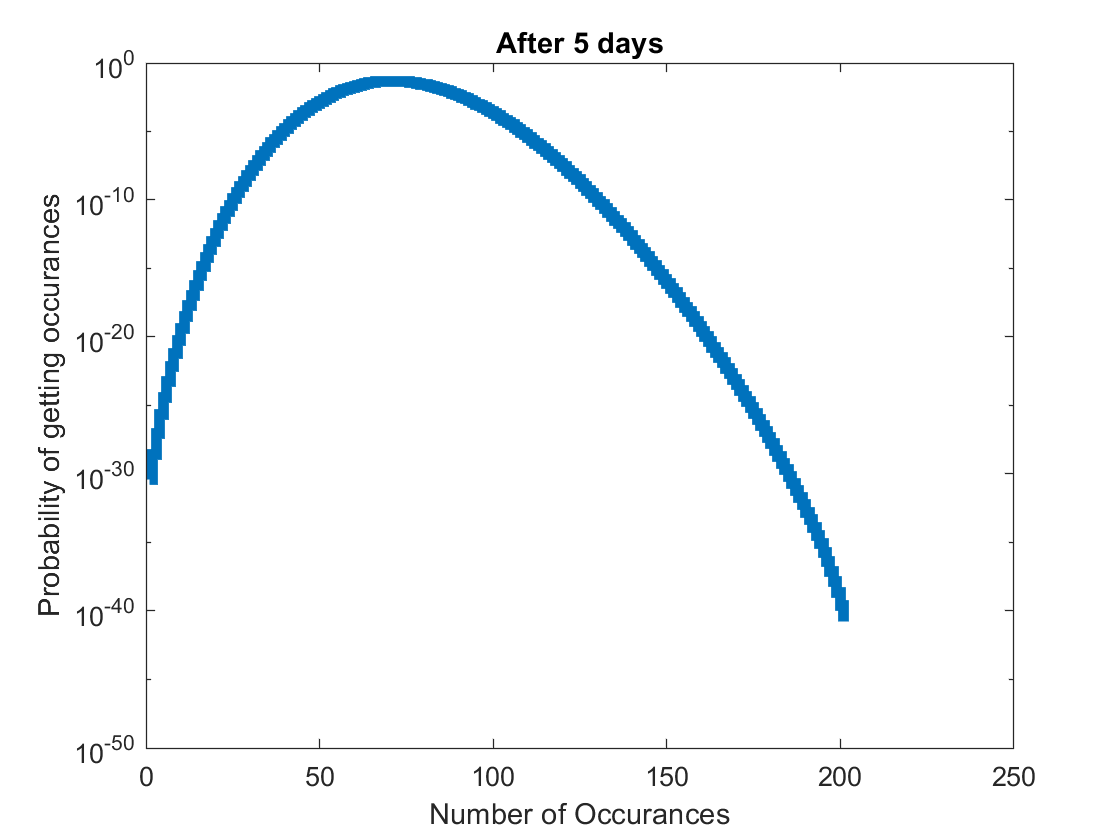

days_3 = conv(days_2,pdf(poisson,x));
days_4 = conv(days_3,pdf(poisson,x));
days_5 = conv(days_4, pdf(poisson,x));

stairs(days_5,"LineWidth",4);
set(gca,'YScale','log')
title("After 5 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

After 5 days, the distribution is still poisson. This makes sense since we are still measuring the same background distribution. Nothing about the situation has changed in the past 5 days. Mathematically it makes sense because we are just convolving or taking the sum of the probabilities of two PDF's of poisson distributions. 

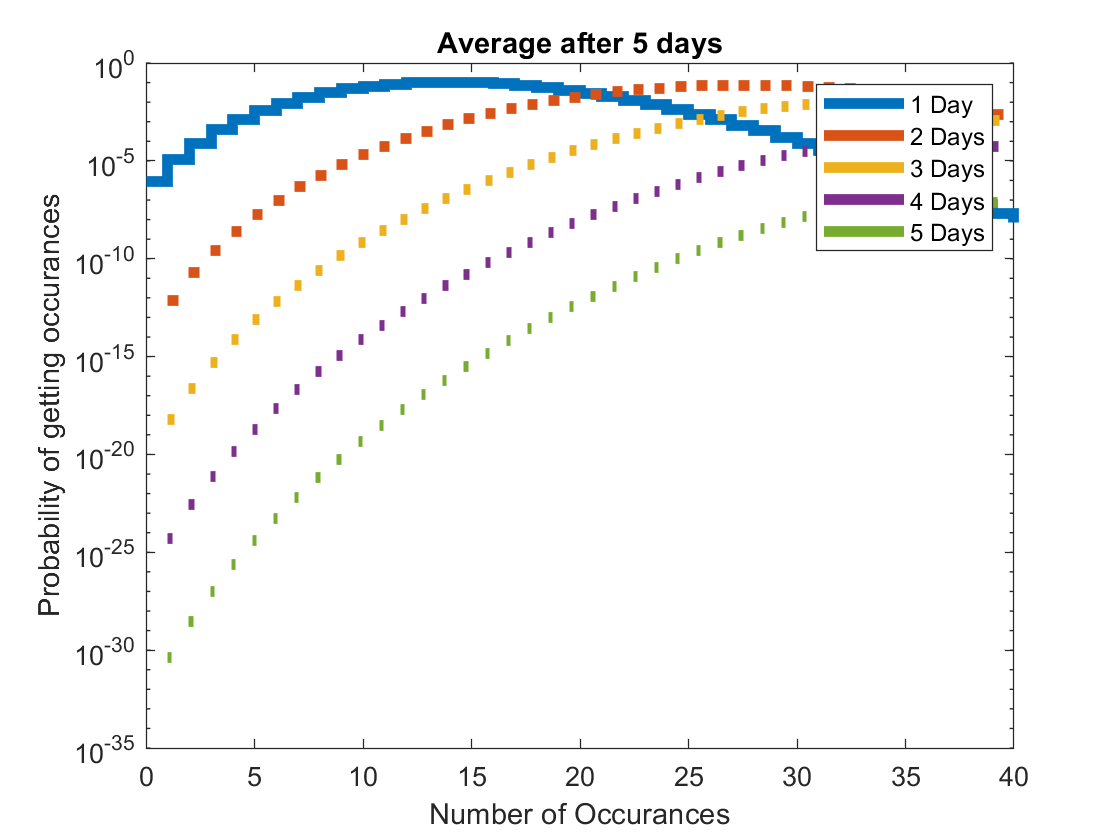

stairs(x,days_1,"LineWidth",4);
hold on
stairs(linspace(1,40,81),ave_2,"LineWidth",4);
stairs(linspace(1,40,121),ave_3,"LineWidth",4);
stairs(linspace(1,40,161),ave_4,"LineWidth",4);
stairs(linspace(1,40,201),ave_5,"LineWidth",4);
set(gca,'YScale','log')
title("Average after 5 days")
legend("1 Day", "2 Days", "3 Days", "4 Days", "5 Days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

mean_conv(1) = 14;
mean_conv(2) = sum(ave_2.*linspace(1,40,81))/sum(ave_2, 'all');
mean_conv(3) = sum(ave_3.*linspace(1,40,121))/sum(ave_3, 'all');
mean_conv(4) = sum(ave_4.*linspace(1,40,161))/sum(ave_4, 'all');
mean_conv(5) = sum(ave_5.*linspace(1,40,201))/sum(ave_5, 'all');

hold off

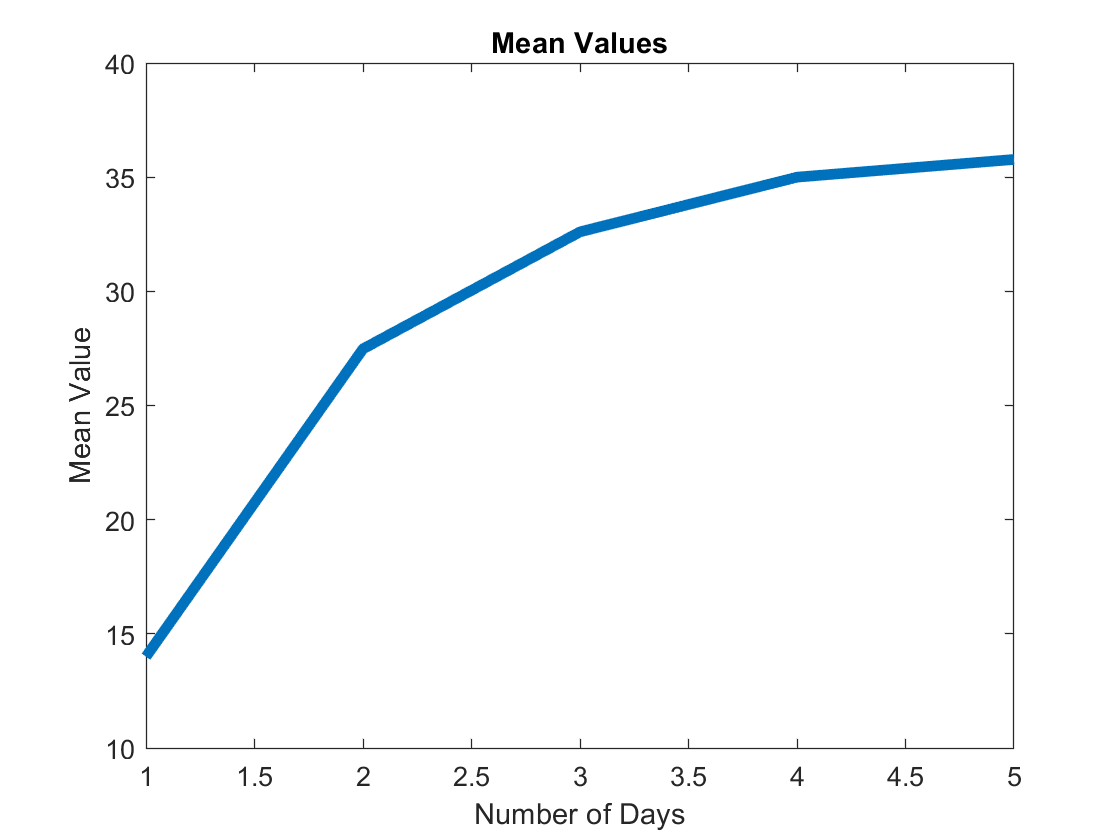

plot(mean_conv,"LineWidth",4)
title("Mean Values")
ylabel("Mean Value")
xlabel("Number of Days")

The average over an increasing range of days becomes more gaussian like due to the central limit theorem. The mean also increases and converges to a mean value. This is shown by calculating the weighted mean of each average distribution and then seeing that the difference between the average is decreasing. This is also shown in the "Mean Values" plot to the right.

We chose 3 days, since we chose Y to be 20, that means we are looking for the sigma of 60 gamma rays.

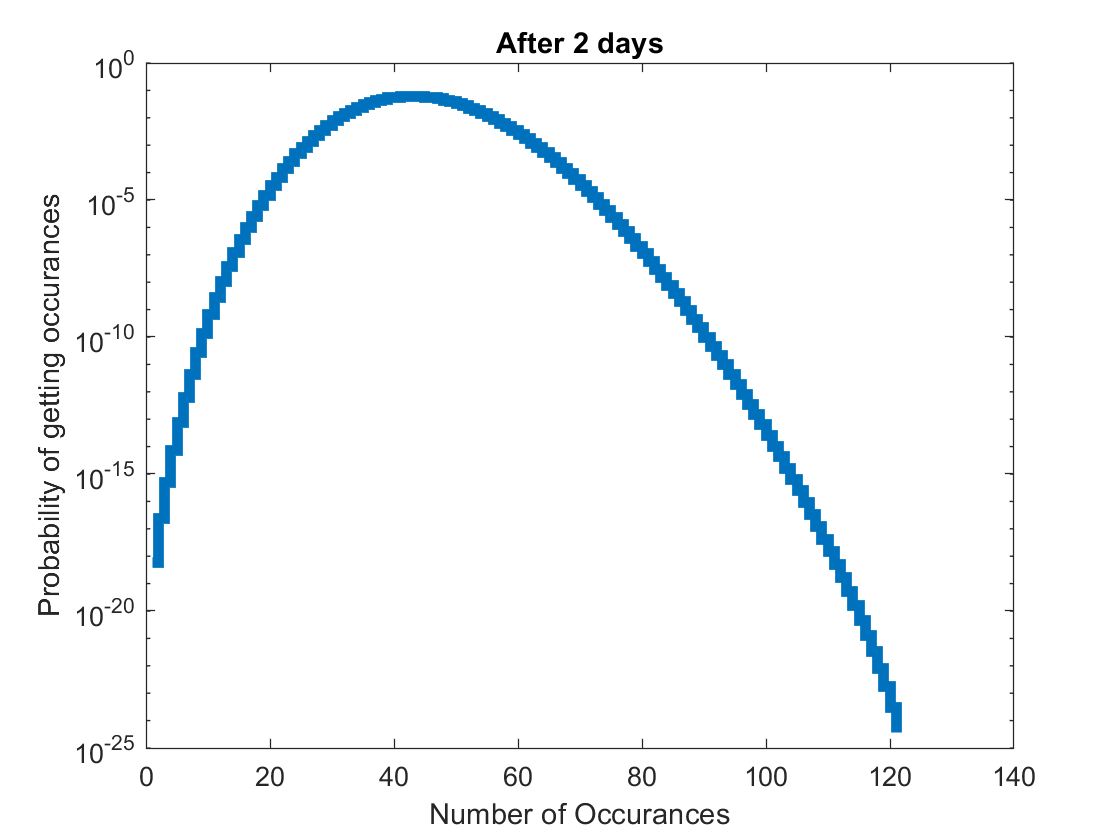

N = 3;
gams = Y*N;

stairs(days_3,"LineWidth",4);
set(gca,'YScale','log')
title("After 2 days")
xlabel("Number of Occurances")
ylabel("Probability of getting occurances")

sig_vals = icdf(poisson, days_3)

sig_vals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     2     3     3     4     4     4     5     5     5     6     6     7     7     7     7     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
